# Steifes System

Wir betrachten ein Modell eines chemischen Reaktionsprozesses (chemische Pyrolyse, siehe Buch):

     
$$y_1'=-k_1 y_1 -k_3 y_1 y_3$$


     
$$y_2'=k_1 y_1 -k_2 y_2 y_3$$


     
$$y_3'=k_1 y_1 -k_2 y_2 y_3-k_3y_1y_3+k_4 y_4$$


     
$$y_4'=k_3 y_1 y_3-k_4y_4$$


      
$$y_5'=k_2 y_2 y_3$$


      
$$y_6'=k_4 y_4$$


für  $t \in [0,T]$, mit Reaktionsgeschwindigkeitskonstanten $k_i$, $i=1,\ldots,4$, und Anfangsbedingungen $y_i(0)=y^i$, $i=1,\ldots,6$.  Für  die Anfangsbedingung wählen wir $y(0)=(1,0,0,0,0,0)$. 

Wir untersuchen folgende zwei konkrete Fälle:

 **Modell**=1 : $k_1=10^{-5}, k_2=10^3, k_3=100, k_4=10$, $T=500$  ("steifes System")

 **Modell**=2 : $k_1=7.9\cdot10^{-10}, k_2=1.1\cdot10^9, k_3=1.1\cdot 10^7, k_4=1.1\cdot 10^3$, $T=4.5 \cdot 10^4$  ("extrem steifes System",  Beispiel aus dem Buch)

modell=1;
ystart=[1;0;0;0;0;0];
global k;

k=zeros(4,1);
switch modell
    case 1
        disp('Steifes Modell wird betrachtet');
        T=500;
        k(1)=10^(-5); k(2)=10^3; k(3)=100; k(4)=10;
    case 2
        disp('Sehr steifes Modell wird betrachtet');
        T=4.5*10^4;
        k(1)=7.9*10^(-10); k(2)=1.1*10^9; k(3)=1.1*10^7; k(4)=1.1*10^3;
end

Steifes Modell wird betrachtet


Wir betrachten zwei in Matlab zur Verfügung stehende Verfahren: **ode45** und **ode23tb**. Die **ode45-**Routine basiert auf einem eingebetteten Runge-Kutta-Verfahren. Die **ode23tb**-Routine basiert auf einer Variante des BDF2-Verfahrens. Hierbei wird die Trapezmethode  mit der BDF2-Methode wie folgt kombiniert:

   ${y^{j+\frac12}}=y^j+\frac{h}{2}\big(f(t_j,y^j)+f(t_{j+\frac12},y^{j+\frac12})\big)$   (Trapezmethode mit Schrittweite $\frac12 h$)

   $y^{j+1}=\frac{4}{3} y^{j+\frac12}-\frac13 y^j+\frac23f(t_{j+1},y^{j+1})$       (BDF2 mit Zwischenwert $y^{j+\frac12}$ aus der Trapezmethode).

Dieses Verfahren hat Konsistenzordnung 2 und ist A-stabil. Außerdem hat es die Form eines Einschrittverfahrens und kann mit adaptiver Schrittweitensteuerung relativ einfach kombiniert werden.

Die Wahl des Verfahrens wird über den Parameter** choice **gesteuert:

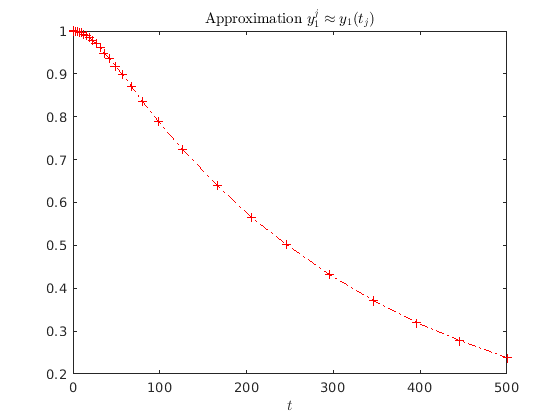

choice=2; 
hold off;

switch choice
    case 1
        disp('Matlabroutine ode45 wird verwendet');
        [Zeit,Y]=ode45(@f,[0 T],ystart);
    case 2
        disp('Matlabroutine ode23tb wird verwendet');  
        [Zeit,Y]=ode23tb(@f,[0 T],ystart);
end

Matlabroutine ode23tb wird verwendet


Die berechneten Konzentrationen $y_i^n\approx y_i(T)$, $i=1,\ldots,6$, am Endzeitpunkt werden ausgegeben, und den Verlauf über die Zeit der berechneten Konzentration $y_i^j, j=0,\ldots,n,$  ($i=1,\ldots,6$) wird gezeigt. Außerdem wird (in loglog-Skalierung) die  adaptive Zeitschrittweite gezeigt.

scaling=1;
fprintf('\nBerechnete Approximationen der Konzentrationen am Endzeitpunkt:\n');


Berechnete Approximationen der Konzentrationen am Endzeitpunkt:


format shorte;
Resultat=Y(length(Zeit),:)'

Resultat =    2.3825e-01
   9.3913e-05
   2.7764e-05
   6.6149e-05
   2.6327e-03
   7.5896e-01


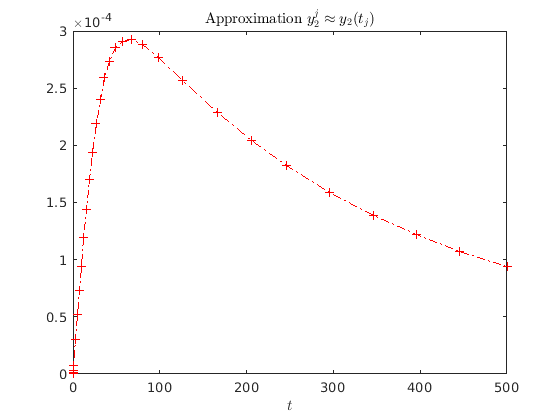

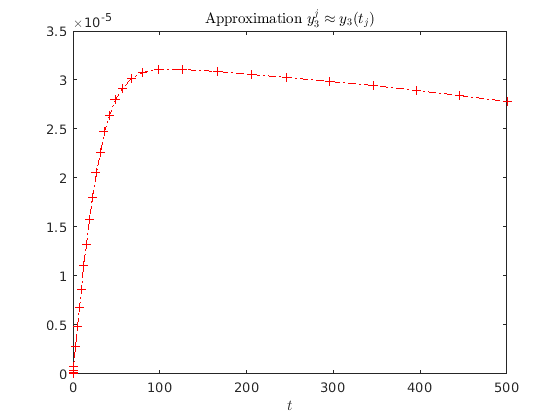

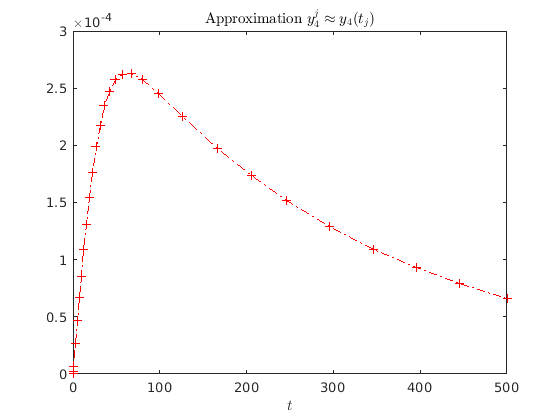

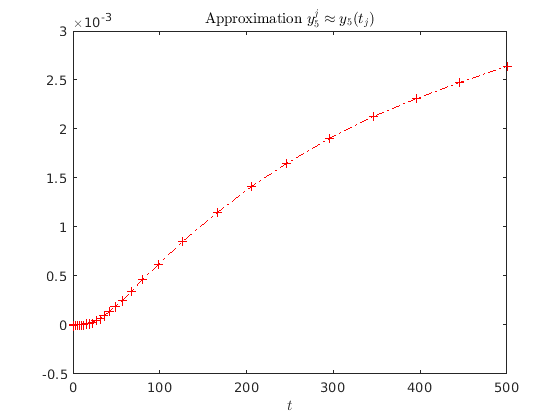

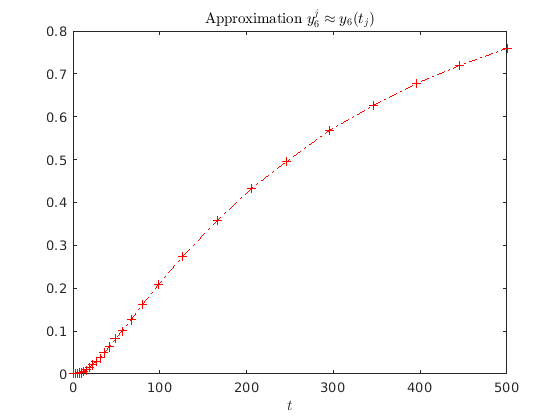

plotresults(scaling,Zeit,Y); 

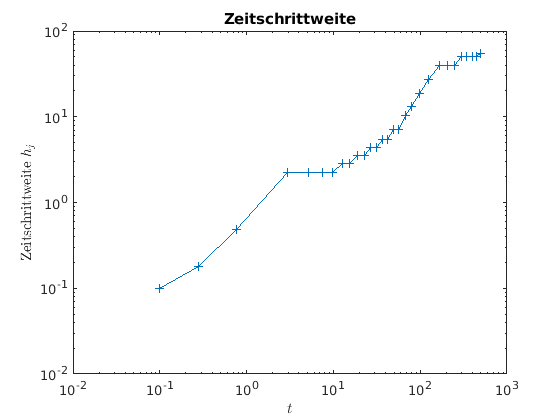

plotSchrittweite(Zeit);

fprintf('\nAnzahl der verwendeten Zeitschritte:\n');


Anzahl der verwendeten Zeitschritte:


length(Zeit)-1

ans =     29


# Aktivität:

Verwenden  Sie beide Verfahren (**ode45** und **ode23tb**) und beurteilen  Sie die Qualität der  Ergebnisse. 

Beachten Sie die unterschiedlichen Skalierung der $y$-Achse bei den Grafiken für $y_i^j$, $i=1,\ldots,6$. 

Mit dem Parameter **scaling (**mit Werten in $[0.5,1]$) werden in den Grafiken für $y_i^j$, $i=2,3,4$ die $x$-Achsen anders skaliert. Mit einer geeigneten Skalierung sind im Fall des extrem steifen Systems die sehr steilen Verläufe am Anfang des Zeitintervalls besser sichtbar.

function fout=f(t,y) %wertet die rechte Seite der DGLn aus
    global k;
    k1=k(1); k2=k(2); k3=k(3); k4=k(4);
    fout=zeros(6,1);
    fout(1)=-k1*y(1)-k3*y(1)*y(3);
    fout(2)=k1*y(1)-k2*y(2)*y(3);
    fout(3)=k1*y(1)-k2*y(2)*y(3)-k3*y(1)*y(3)+k4*y(4);
    fout(4)=k3*y(1)*y(3)-k4*y(4);
    fout(5)=k2*y(2)*y(3);
    fout(6)=k4*y(4);
end

function plotresults(scaling,Zeit,Y) % Plottet das Ergebniss
    figure(1)
    plot(Zeit,Y(:,1),'r-.+')
    title('Approximation $y_1^j\approx y_1(t_j)$','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    figure(2);
    m=length(Zeit);
    reduce=round(scaling*m);
    plot(Zeit(1:reduce),Y(1:reduce,2),'r-.+');
    title('Approximation $y_2^j\approx y_2(t_j)$','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    figure(3); 
    plot(Zeit(1:reduce),Y(1:reduce,3),'r-.+');
    title('Approximation $y_3^j\approx y_3(t_j)$','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    figure(4); 
    plot(Zeit(1:reduce),Y(1:1:reduce,4),'r-.+');
    title('Approximation $y_4^j\approx y_4(t_j)$','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    figure(5);
    plot(Zeit,Y(:,5),'r-.+');
    title('Approximation $y_5^j\approx y_5(t_j)$','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    figure(6);
    plot(Zeit,Y(:,6),'r-.+ ');
    title('Approximation $y_6^j\approx y_6(t_j)$','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
 end

function plotSchrittweite(t)
    Zeitschritt= diff(t); % berechnet [t(2)-t(1), ..., t(n)-t(n-1)]
    Zeitschritt= [0; Zeitschritt]; % damit t und Zeitschritt dieselbe Groesse haben
    figure(7);
    loglog(t,Zeitschritt,'-+');
    title('Zeitschrittweite');
    xlabel('$t$','Interpreter','latex');
    ylabel('Zeitschrittweite $h_j$','Interpreter','latex');
end